clc;
clear;
r_s_val = 0.025;
r_p_val = 0.032;
b_val = 0.003;
servo_max = 45;
servo_min = -45;
r_val = 0.05;
warning('off','all')
warning

All warnings have the state 'off'.


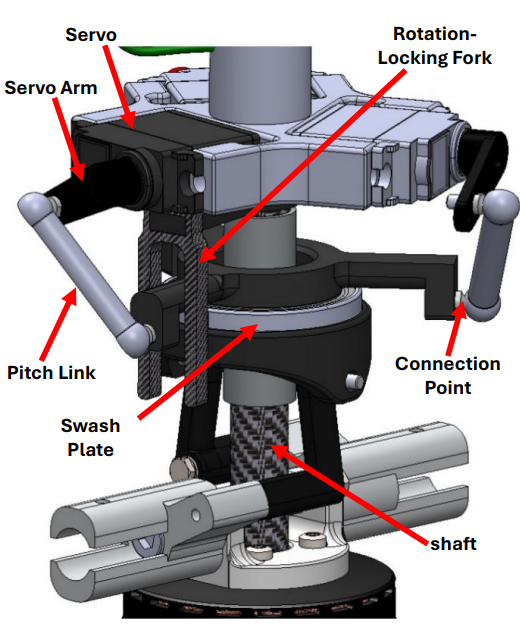

syms r_p r r_s r_w real
assume(r_p > 0);
assume(r_s > 0);
assume(r_w > 0);
assume(r > 0);

Above declares all variables, below is their definitons

p = the points in the servo assembly. So p1 is the center of the servo, p2 is the connection of the servo horn and pitch link, and p3 is the connection to the swash plate

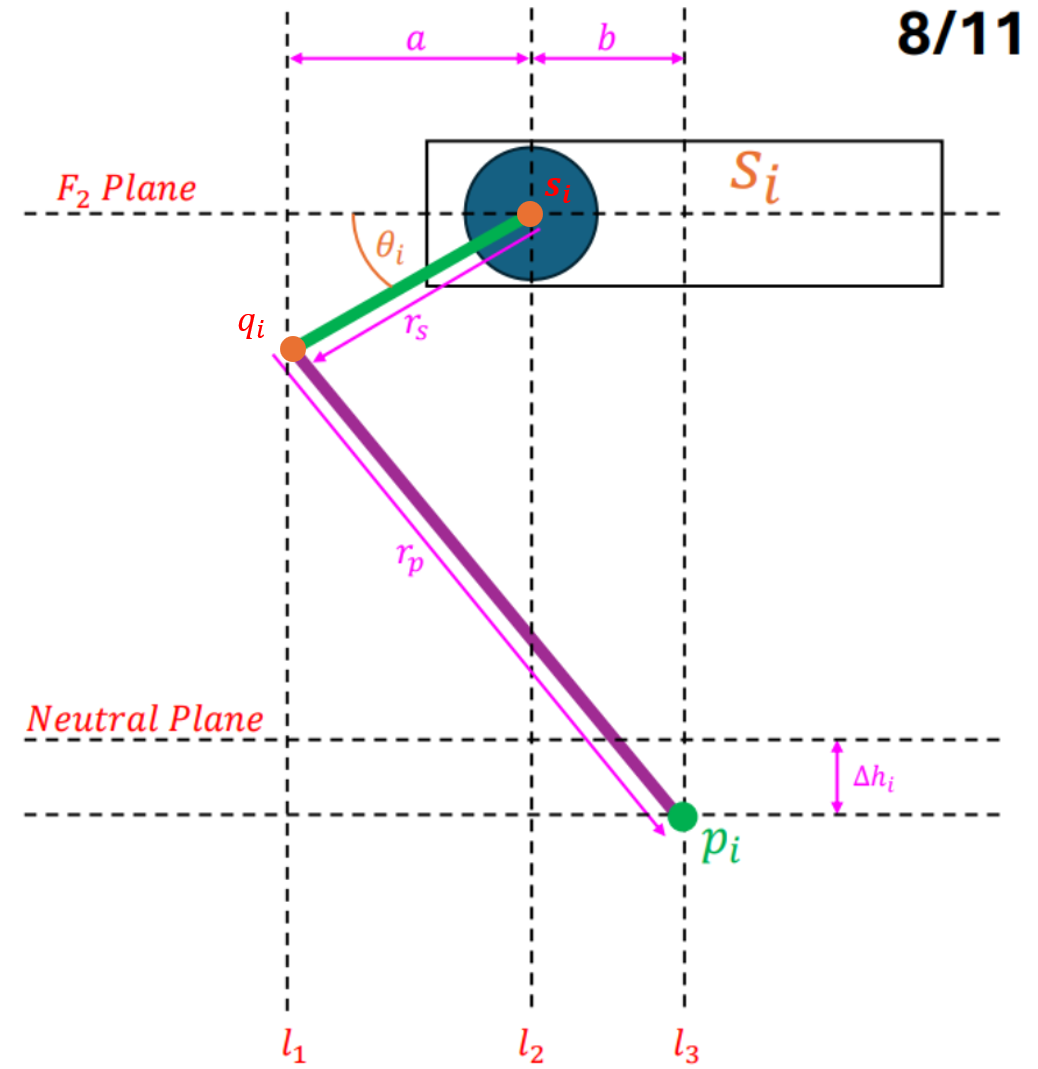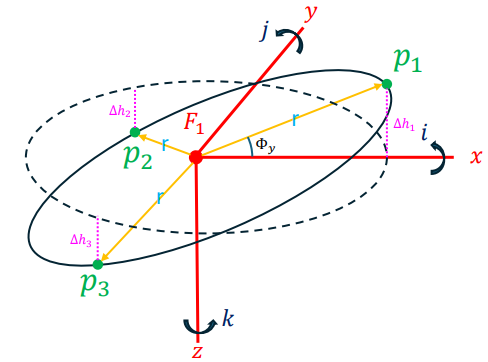


% Define the position of each point 
syms s1_x s1_y s1_z s2_x s2_y s2_z s3_x s3_y s3_z real % center of servo rotation
syms q1_x q1_y q1_z q2_x q2_y q2_z q3_x q3_y q3_z real % end of servo horn
syms p1_x p1_y p1_z p2_x p2_y p2_z p3_x p3_y p3_z real % connection of pitch link to swash plate
syms theta_1 theta_2 theta_3 real
p = [
    p1_x , p2_x, p3_x ;
    p1_y , p2_y, p3_y ;
    p1_z , p2_z, p3_z ;
    ];
q = [
    q1_x , q2_x, q3_x ;
    q1_y , q2_y, q3_y ;
    q1_z , q2_z, q3_z ;
    ];
s = [
    s1_x , s2_x, s3_x ;
    s1_y , s2_y, s3_y ;
    s1_z , s2_z, s3_z ;
    ];

theta = [theta_1, theta_2, theta_3]

$$theta = \left(\begin{array}{ccc} \theta_{1} & \theta_{2} & \theta_{3} \end{array}\right)$$

Use polar co-ordinates to describe the position of the end of the servo hornes (r_i) as a function of the angles of each servo. Below are the steps:

1) points s lie on the F_2 plane, about a circle of radius r. This is of height z = 0 on the F_2 plane. The servos rotate on the plane normal to the radius of the circle. Find all normal vectors and points s.


% The spacing of servos around the unit circle
gamma = 2*pi/3;
angles = [0, gamma, 2*gamma]

angles =          0    2.0944    4.1888



% Assign values of gamma
for i = 1:3
    servo_angle = angles(i);
    s(:,i) = [r*cos(servo_angle); r*sin(servo_angle); 0];  % point on circle in xy-plane
end
s

$$s = \left(\begin{array}{ccc} r & -\frac{r}{2} & -\frac{r}{2}\\ 0 & \frac{\sqrt{3}\,r}{2} & -\frac{\sqrt{3}\,r}{2}\\ 0 & 0 & 0 \end{array}\right)$$


% NORMAL VECTORS TO S
norms = simplify(sqrt(sum(s.^2, 1)));
n = simplify(s ./ norms);

Here is me trying to do it with the equations of the plane:

So the equation for a plane can be given by 0 = n . (r - r_0), where n is a normal vector and r_0 is a point on the plane. For the rotation of the servos, we know that point s is the starting points (r_0), and the vector connecting the origin the the servo is a normal vector to that plane (s). So we try to 

% ok so, s are the points on the plane, and n is the normal vector to the
% plane

% First multiply
d = simplify(sum(n .* s, 1))

$$d = \left(\begin{array}{ccc} r & r & r \end{array}\right)$$


planes = [n', d']

$$planes = \left(\begin{array}{cccc} 1 & 0 & 0 & r\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0 & r\\ -\frac{1}{2} & -\frac{\sqrt{3}}{2} & 0 & r \end{array}\right)$$

The code segment below plots "planes" and s in a 3d figure so that you can visualise that the correct thing is happenning

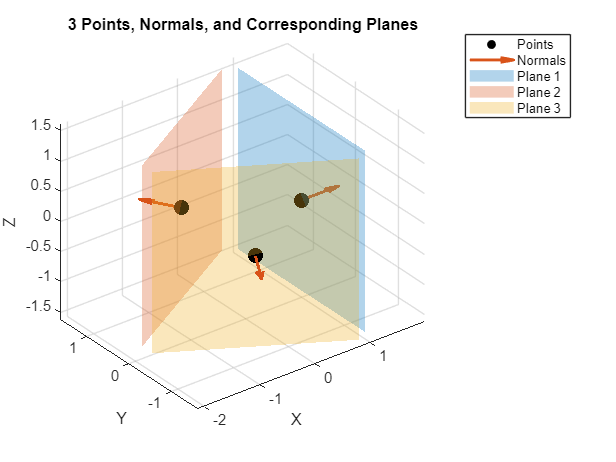

r_value = 1;
rs_value = 0.5;
local_s     = double(subs(s, r, r_value));
local_n     = double(subs(n, r, r_value));

% plotting
figure; 
hold on; 
axis equal;
view(3)
grid on

scatter3(local_s(1,:), local_s(2,:), local_s(3,:), 100, 'k', 'filled');
quiver3(local_s(1,:), local_s(2,:), local_s(3,:), ...
        local_n(1,:), local_n(2,:), local_n(3,:), ...
        0.5, 'LineWidth', 2, 'MaxHeadSize', 0.5);

L = 1.5*r_value;                 
gridPts = linspace(-L, L, 30); 

colors = lines(3);     
for i = 1:3
    ni = local_n(:,i);     
    pi = local_s(:,i);    


    B = null(ni'); 

    [A,Bb] = meshgrid(gridPts, gridPts);


    X = pi(1) + B(1,1)*A + B(1,2)*Bb;
    Y = pi(2) + B(2,1)*A + B(2,2)*Bb;
    Z = pi(3) + B(3,1)*A + B(3,2)*Bb;

    surf(X, Y, Z, ...
         'FaceColor', colors(i,:), ...
         'FaceAlpha', 0.3, ...
         'EdgeColor', 'none');
end
xlabel('X'); 
ylabel('Y'); 
zlabel('Z');
title('3 Points, Normals, and Corresponding Planes');
legend({'Points','Normals','Plane 1','Plane 2','Plane 3'}, ...
       'Location','bestoutside');
hold off

2) Now "planes" contains all the planes. What now needs to be done is find the cartesian co-ordinates of the servo arm. how this will be done is to calculate the (x,z) co-ordinates of the rotation, and then map it onto the new plane.

servo_tips = [ r_s .* cos(theta) ; r_s .* sin(theta) ]

$$servo\_tips = \left(\begin{array}{ccc} r_{s}\,\cos\left(\theta_{1}\right) & r_{s}\,\cos\left(\theta_{2}\right) & r_{s}\,\cos\left(\theta_{3}\right)\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)$$


u = [-s(2,:); 
      s(1,:); 
      zeros(1,3)];
u = u ./ sqrt(sum(u.^2,1));

v = cross(n, u, 1);


%    servo_tips(1,i) = u_i , servo_tips(2,i) = v_i
delta = u .* servo_tips(1,:) + v .* servo_tips(2,:);

q = s + delta

$$q = \begin{array}{l} \left(\begin{array}{ccc} r & -\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2} & \frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}-\frac{r}{2}\\ r_{s}\,\cos\left(\theta_{1}\right) & \sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2} & -\sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,r}{2} \end{array}$$

Now to plot these lines on a new graph so that I can see the affect of them and how they are evaluated in 3d space

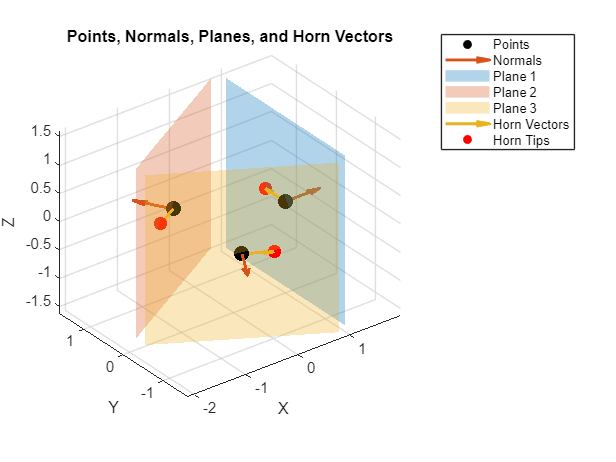

% parameters
r_value     = 1;
rs_value = 0.5;
theta_value = [0; 0; 0];   % all servos at zero angle

% substitute and convert
local_s = double(subs(s, [r, r_s], [r_value, rs_value]));
local_n = double(subs(n, [r, r_s], [r_value, rs_value]));
% local_s = double(subs(s, r_s, rs_value));
% local_n = double(subs(n, r_s, rs_value));

% plotting setup
figure;
hold on;
axis equal;
view(3);
grid on;

scatter3( local_s(1,:), local_s(2,:), local_s(3,:), 100, 'k', 'filled' );
quiver3( local_s(1,:), local_s(2,:), local_s(3,:), ...
         local_n(1,:), local_n(2,:), local_n(3,:), ...
         0.5, 'LineWidth',2, 'MaxHeadSize',0.5 );

colors = lines(3);
L      = 1.5 * r_value;
for i = 1:3
    ni = local_n(:,i);        % normal for plane i
    pi = local_s(:,i);        % a point on plane i

    Bi = null(ni');           % 3×2 basis for the plane

    % four corners of a square of side 2L in that plane
    corners = [ ...
        pi +  L*Bi(:,1) +  L*Bi(:,2), ...
        pi +  L*Bi(:,1) -  L*Bi(:,2), ...
        pi -  L*Bi(:,1) -  L*Bi(:,2), ...
        pi -  L*Bi(:,1) +  L*Bi(:,2)  ...
    ]';  % 4×3: each row is one vertex

    patch('Vertices', corners, 'Faces', [1 2 3 4], ...
          'FaceColor',   colors(i,:), ...
          'FaceAlpha',   0.3, ...
          'EdgeColor',   'none');
end

% 3) compute & plot the horn‐tip vectors on each plane
% 3a) 2D offsets in each plane
servo2D = [ rs_value*cos(theta_value)'; 
            rs_value*sin(theta_value)' ];   % 2×3

% 3b) in‐plane basis u (tangent) and v (cross)
local_u = [ -local_s(2,:); local_s(1,:); zeros(1,3) ];
local_u = local_u ./ vecnorm(local_u,2,1);
local_v = cross(local_n, local_u, 1);

% 3c) lift to 3D
delta = local_u .* servo2D(1,:) + v .* servo2D(2,:);
local_q     = local_s + delta;

% 3d) plot horn vectors and tips
quiver3( local_s(1,:), local_s(2,:), local_s(3,:), ...
         delta(1,:),    delta(2,:),    delta(3,:), ...
         0, 'LineWidth',2, 'MaxHeadSize',0.5 );
scatter3( local_q(1,:), local_q(2,:), local_q(3,:), 80, 'r', 'filled' );

% labels & legend
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Points, Normals, Planes, and Horn Vectors');
legend({ 'Points','Normals',...
         'Plane 1','Plane 2','Plane 3',...
         'Horn Vectors','Horn Tips' }, ...
       'Location','bestoutside');

hold off;


% Uncomment this to see the interactive slider window
% servo_swash_slider(s,n,r);

3) Now that the vectors of q are found, we need to  solve the equations for the points p. what is known for certain is that the radius between q_i and p_i is set by the length of the pitch links. Below we define the constraint equation that bind the magnitude

How to do this is that we will do some crazy shit. We have these 3 points, now we need to find the plane that separates them.

We will just find the point that satisfies the swash plate radius. There are 2 key constraints.

1) The distance between the points p and the servo horn tips is the length of the pitch link

2) That the three points must form a circle centered at x=y=0.

syms z_c r_c z_w real
swash_center = [0; 0; z_w]; % as the swash plate is restricted to only move up and down the  
q

$$q = \begin{array}{l} \left(\begin{array}{ccc} r & -\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2} & \frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}-\frac{r}{2}\\ r_{s}\,\cos\left(\theta_{1}\right) & \sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2} & -\sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ r_{s}\,\sin\left(\theta_{1}\right) & r_{s}\,\sin\left(\theta_{2}\right) & r_{s}\,\sin\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,r}{2} \end{array}$$

Ok bitches, lets dig in. So what is known are the following assumptions (see diagram). **q_i is the intersection of l_4 and l_1**

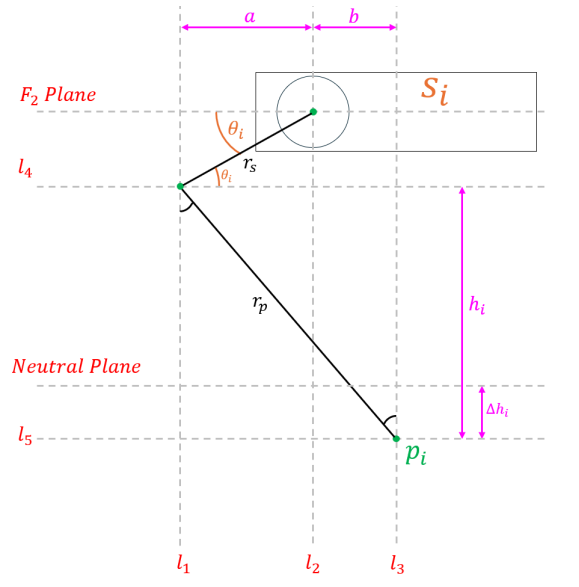 

(1) The pitch link can move up and down along l_1 (ONLY)

(2) The point p_i can roll move into and out of the page 

(3) On the above figure. distance b remains constant, wheras distance a is variable

(4) The distance r_p is in 3d space, meaning in 2d this may not always be 

**GOAL:** The points q is above, we need to map this to point p in 3d space, as a function of theta.

ok now time to solve. we could not use "solve" because:

1) The goal is to actually find the equations of motion, hence if you solve you only get 1 configutarion

2) There are too many parameters so there is no way that this was going to be solved.

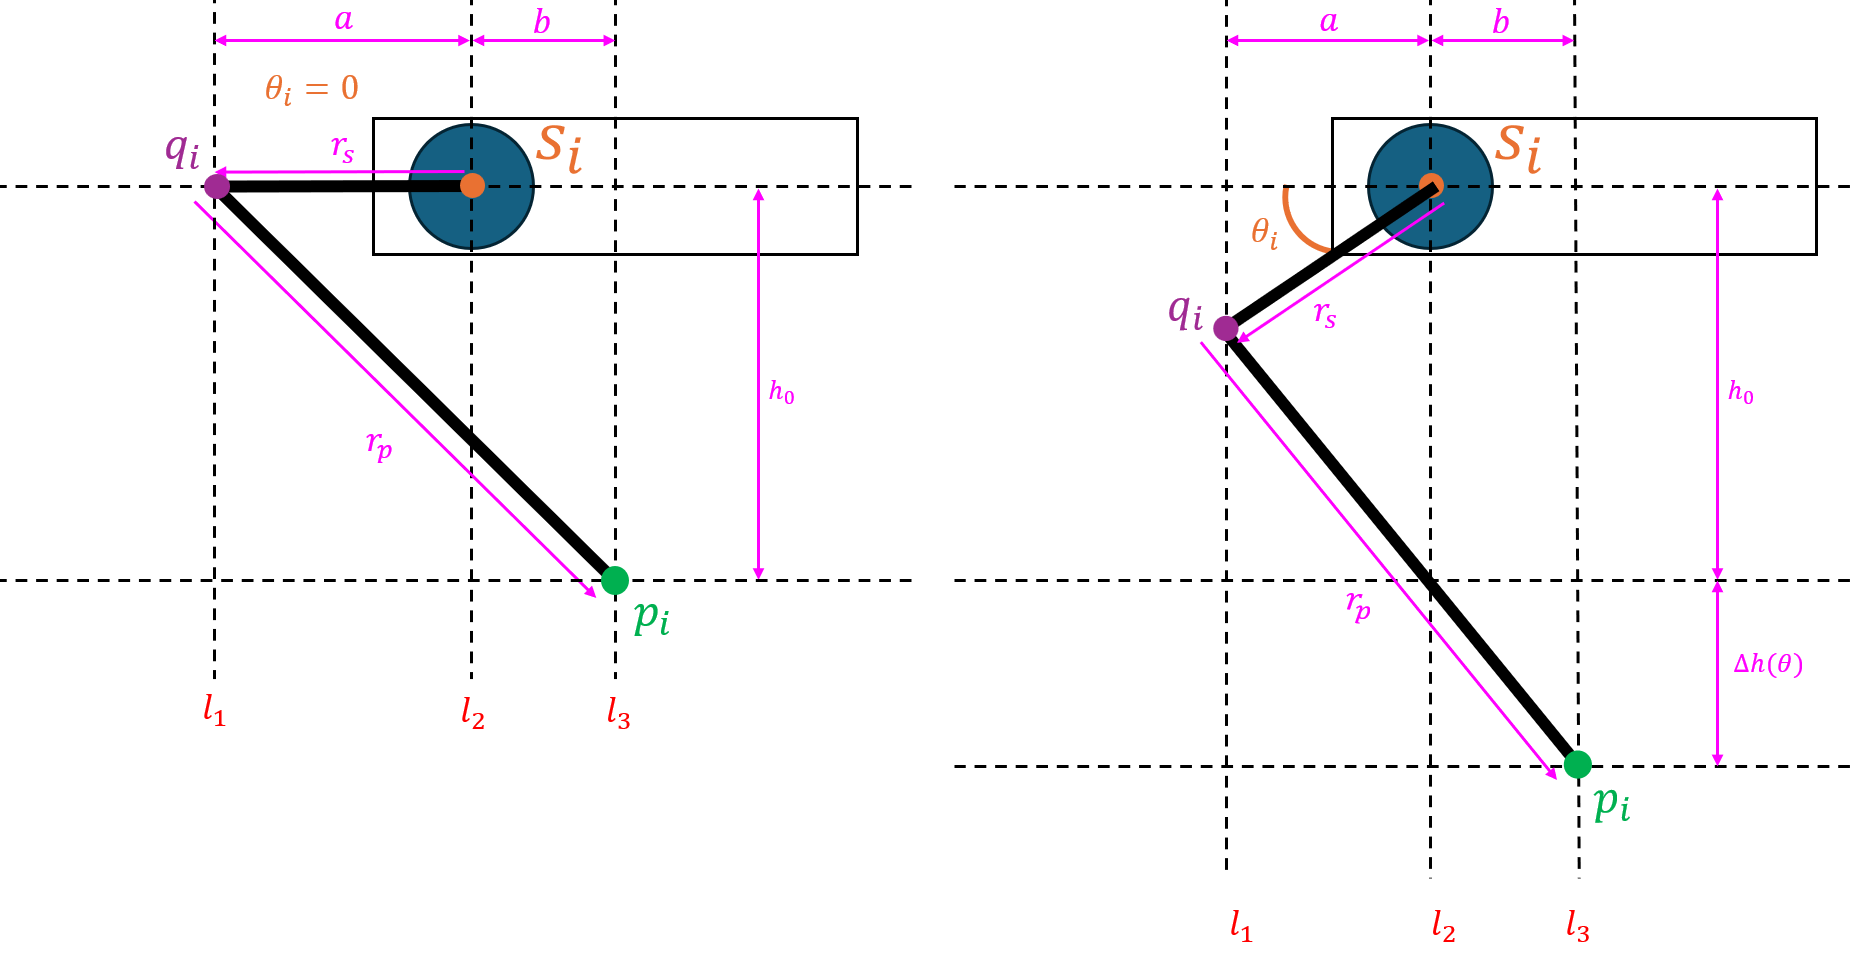

OK so here is the neutral position with all thetas equal zero, the goal is to find dp/dtheta so that then the differential equations can be sovled

what this should give is a line along the z plane where this point can land. once I have that, I can then begin to find the angle of this fucking plate 

r_s_val = 0.025;
r_p_val = 0.032;
b_val = 0.003;

Now it is time to do some mapping from q to p. We know q points, so find p when q = 0 which is just done by solvingthe equation. there are 2 solutions, want the negative one

syms h_0 dh b th real
triangle_constraint = r_p^2 == h_0^2 + (r_s + b)^2;
q_p_constraint = r_p^2 == (r_s * cos(th) + b )^2 + ( r_s * sin(th) - (h_0 + dh) )^2 %th is a dummy variable for theta

$$q\_p\_constraint = {r_{p}}^{2}={\left(\mathrm{dh}+h_{0}-r_{s}\,\sin\left(\mathrm{th}\right)\right)}^{2}+{\left(b+r_{s}\,\cos\left(\mathrm{th}\right)\right)}^{2}$$

Now that we have the triangle, we can solve for  

sol_triangle = solve(triangle_constraint, h_0);
sol_q_p = solve(q_p_constraint, dh);


sol_triangle = simplify(sol_triangle(2))

$$sol\_triangle = -\sqrt{r_{p}-b-r_{s}}\,\sqrt{b+r_{p}+r_{s}}$$

sol_q_p = simplify(sol_q_p(2))

$$sol\_q\_p = r_{s}\,\sin\left(\mathrm{th}\right)-h_{0}-\sqrt{b-r_{p}+r_{s}\,\cos\left(\mathrm{th}\right)}\,\sqrt{-b-r_{p}-r_{s}\,\cos\left(\mathrm{th}\right)}$$

Here is all the neutral heights

h0_expr   = simplify( sol_triangle );
dh_expr   = simplify( subs( sol_q_p, h_0, h0_expr ) );
dh = matlabFunction( dh_expr, 'Vars', {th, r_p, r_s, b} ) % Later subsitute in values

dh = function_handle with value:
    @(th,r_p,r_s,b)sqrt(-b+r_p-r_s).*sqrt(b+r_p+r_s)+r_s.*sin(th)-sqrt(b-r_p+r_s.*cos(th)).*sqrt(-b-r_p-r_s.*cos(th))


% a is the vector between q and p
syms h_1 h_2 h_3 real
syms a_x1 a_x2 a_x3 a_y1 a_y2 a_y3 real
a_x = [a_x1, a_x2, a_x3];
a_y = [a_y1, a_y2, a_y3];
a = [a_x ; a_y ; dh(theta(1), r_p, r_s, b) + h0_expr, dh(theta(2), r_p, r_s, b) + h0_expr, dh(theta(3), r_p, r_s, b)+ h0_expr];

p = simplify(q + a)

$$p = \begin{array}{l} \left(\begin{array}{ccc} a_{\mathrm{x1}}+r & a_{\mathrm{x2}}-\frac{r}{2}-\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{2}\right)}{2} & a_{\mathrm{x3}}-\frac{r}{2}+\frac{\sqrt{3}\,r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ a_{\mathrm{y1}}+r_{s}\,\cos\left(\theta_{1}\right) & a_{\mathrm{y2}}+\sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{2}\right)}{2} & a_{\mathrm{y3}}-\sigma_{1}-\frac{r_{s}\,\cos\left(\theta_{3}\right)}{2}\\ 2\,r_{s}\,\sin\left(\theta_{1}\right)-\sqrt{b-r_{p}+r_{s}\,\cos\left(\theta_{1}\right)}\,\sqrt{-b-r_{p}-r_{s}\,\cos\left(\theta_{1}\right)} & 2\,r_{s}\,\sin\left(\theta_{2}\right)-\sqrt{b-r_{p}+r_{s}\,\cos\left(\theta_{2}\right)}\,\sqrt{-b-r_{p}-r_{s}\,\cos\left(\theta_{2}\right)} & 2\,r_{s}\,\sin\left(\theta_{3}\right)-\sqrt{b-r_{p}+r_{s}\,\cos\left(\theta_{3}\right)}\,\sqrt{-b-r_{p}-r_{s}\,\cos\left(\theta_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,r}{2} \end{array}$$

Now, we try to solve for a_xi and a_yi in each of the above expressions by using the co-ordiante mapping to find the direction of lines l_3 in the figure above. Because of the rotational constriant, the pitch link may only move in between the 

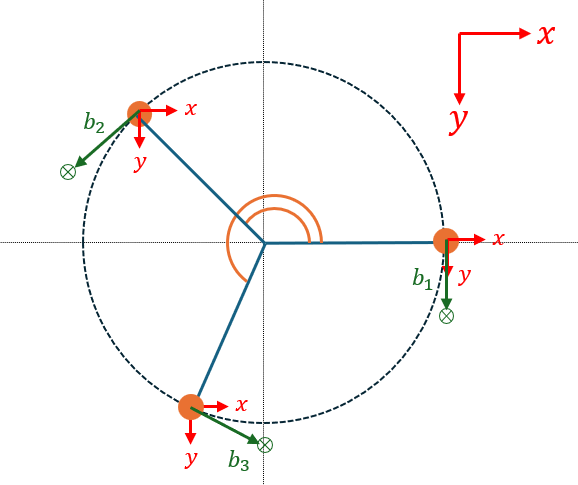

% radial_constraint = 
% 